% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

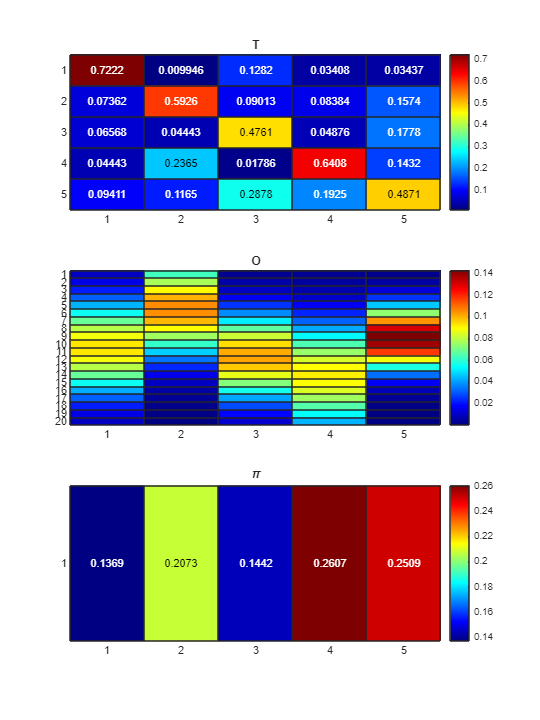

k = 5;
d = 20;

options.method = "random";
options.lambda = 5;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);


figure('Renderer', 'painters', 'Position', [10 10 900 1200])


subplot(3, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(3, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

subplot(3, 1, 3);
h = heatmap(pi, Colormap=jet());
h.Title = '\pi';

Generate an observational sequence based on the defined HMM

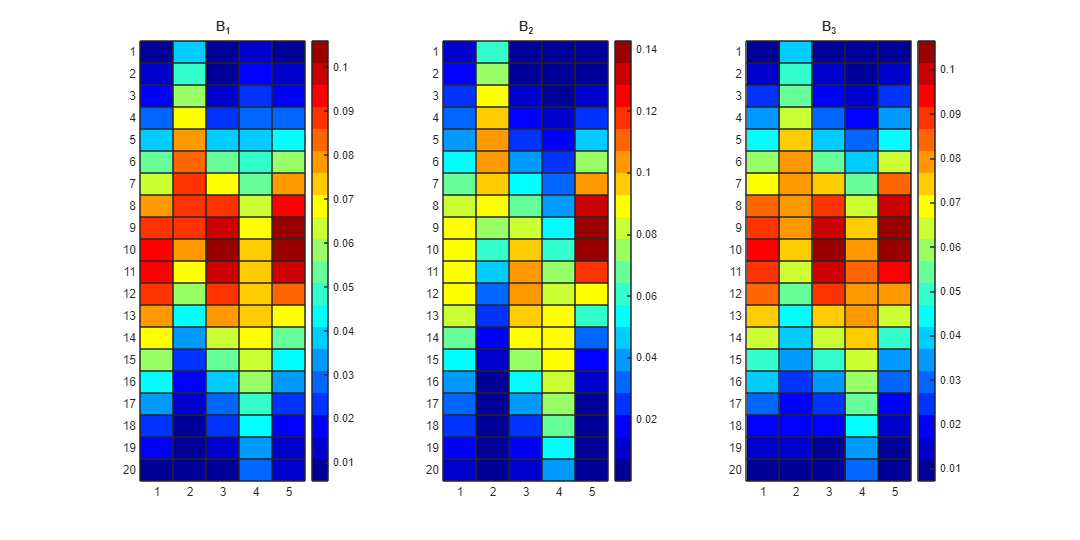

U = {};
U{1} = Stochasticize(O * diag(pi) * T' * inv(diag(T * pi')));
U{2} = O;
U{3} = Stochasticize(O * T);
P3_inf = cpdgen(U)/k;

PlotFactorMatrices(U)

T_seq = 1e6;

Taug = [0, pi; zeros(k, 1), T'];
Oaug = [zeros(1, d); O'];
[seq,states] = hmmgenerate(T_seq, Taug, Oaug);

M3 = ProbabilityTensorGenerate(seq, 3, d);
M2 = ProbabilityTensorGenerate(seq, 2, d);

Estimate the HMM using NNMF algorithm

options = {};
options.maxIter = 1e3;
options.rho = 0.001;
options.epsilon = 1e-10;
options.delta = 1e-10;

tic
[A, B, C, D, convergence] = JPT_NTF(M3, M2, k, d, options);

    "Early NTF termination, minimal change between iterations "



toc

Elapsed time is 0.158131 seconds.


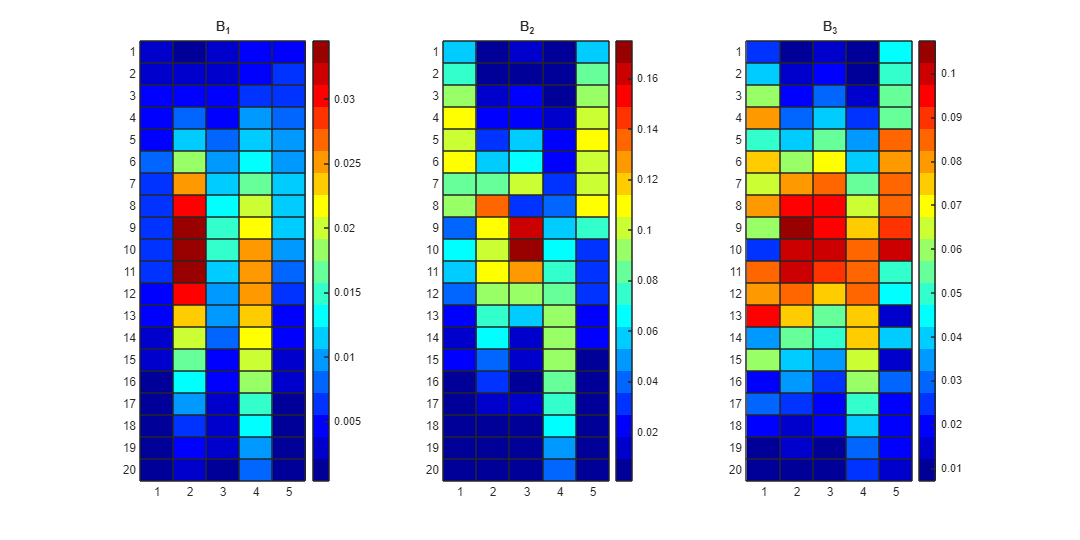


PlotFactorMatrices({A, B, C})

T_hat = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
O_hat = Stochasticize(B);
pi_hat = findStationaryDistribution(T_hat');

P_best = PermutationFitEmission(O, O_hat);

T_hat = P_best * T_hat * P_best';
O_hat = O_hat * P_best';

norm(T-T_hat, "fro") + norm(O-O_hat, "fro")

ans = 0.9635

Plot convergence of the Non-Negative Tensor Factorization algorithm.

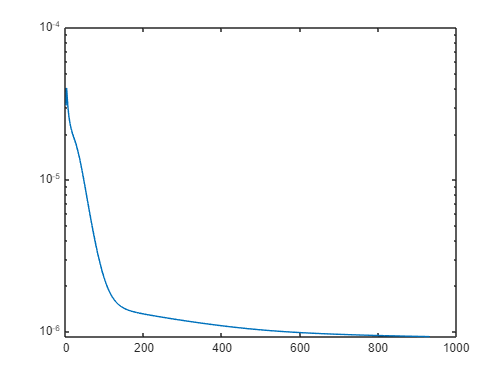

figure();
semilogy(convergence);
yline(convergence(end));

Plot the HMM matrices for the ground truth, emperical methods, and NNMF.

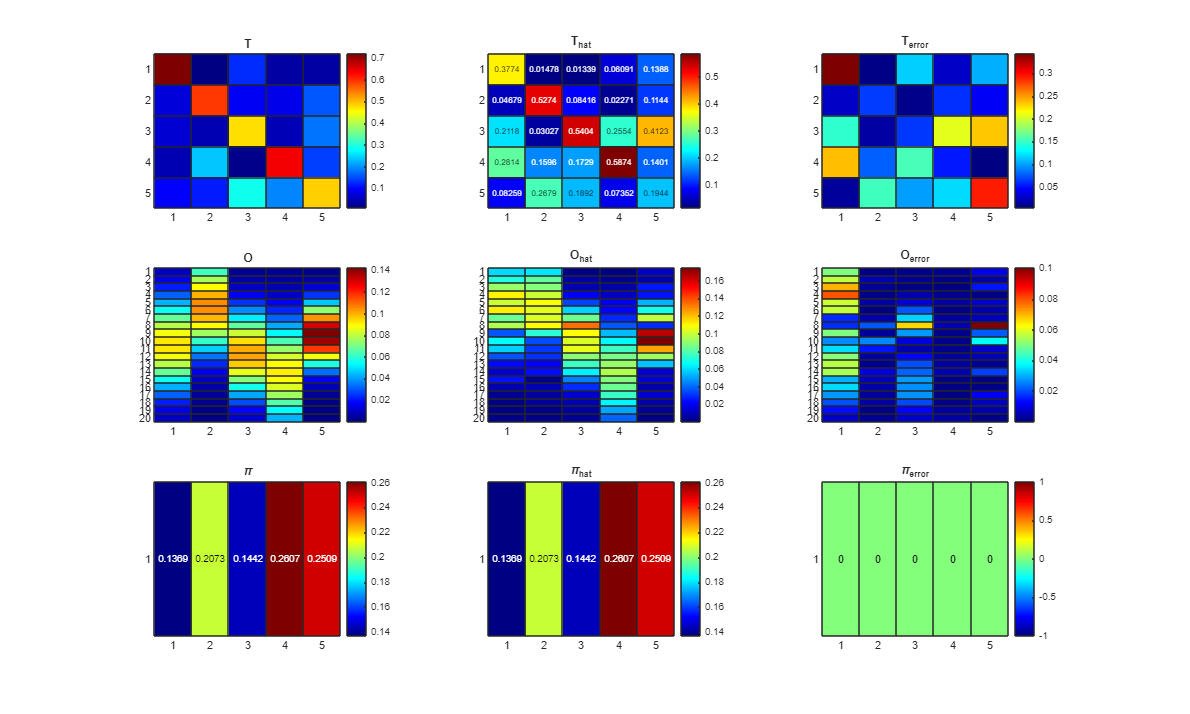

plotHMMError(T, T_hat, O, O_hat, pi, pi_hat);

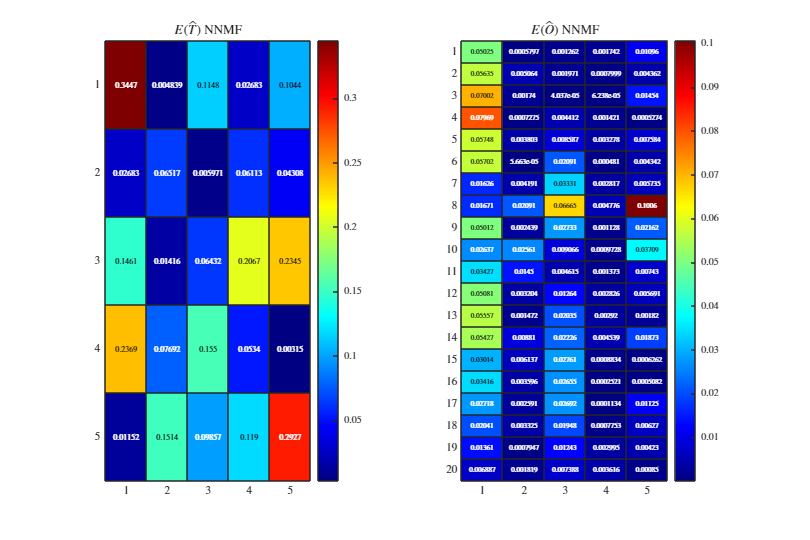


figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(1, 2, 1);
h = heatmap(abs(T - T_hat), Colormap=jet());
h.Title = '$E(\hat{T})$ NNMF';
h.Interpreter = 'latex';

subplot(1, 2, 2);
h = heatmap(abs(O - O_hat), Colormap=jet());
h.Title = '$E(\hat{O})$ NNMF';
h.Interpreter = 'latex';